# Calcalate generation features in 2019

The program is used to calculate generation features of the aggregated units in NYAM, such as max power,. min power, and max ramp rate.

## Import the RGGI generation data

% Import hourly generation data of generators in RGGI database in the 2019 whole year
genFileDir = "D:\EERL\ny_academic_model\data\EPA_AMPD\2019\";
genFileName = "emission*.csv";
generationDataStore = fileDatastore(genFileDir + genFileName, "ReadFcn", @importGenerationData, "UniformRead", true);
generationAll = readall(generationDataStore);

## Import RGGI to NYCA reference table

% Import the reference table from RGGI to NYISO NYCA database
RGGI2NYCA2019 = importRGGI2NYCA("D:\EERL\ny_academic_model\data\EPA_AMPD\RGGI_2_NYCA_2019.xlsx");
generatorCombiner = RGGI2NYCA2019(:, ["NYISOname", "PTID", "FacilityName", "FacilityID", "UnitID", "NYAMUnit", "Region", "UnitType", "FuelType", "NamePlateRatingMW", "GrossLoadMWh"]);
% Exclude generators that are not included in NYAM units
generatorCombiner = generatorCombiner(generatorCombiner.NYAMUnit ~= 'NA',:);
% Exclude generators fueling on wood and refuse (renewable energy)
generatorCombiner = generatorCombiner(generatorCombiner.FuelType ~= "Wood" & generatorCombiner.FuelType ~= "Refuse", :);
% Exclude generators with zero gross load in 2019
generatorCombiner = generatorCombiner(generatorCombiner.GrossLoadMWh > 0, :);
% Remove unused categories
generatorCombiner.NYISOname = removecats(generatorCombiner.NYISOname);
generatorCombiner.PTID = removecats(generatorCombiner.PTID);
generatorCombiner.FacilityName = removecats(generatorCombiner.FacilityName);
generatorCombiner.FacilityID = removecats(generatorCombiner.FacilityID);
generatorCombiner.UnitID = removecats(generatorCombiner.UnitID);
generatorCombiner.NYAMUnit = removecats(generatorCombiner.NYAMUnit);
generatorCombiner.Region = removecats(generatorCombiner.Region);
generatorCombiner.UnitType = removecats(generatorCombiner.UnitType);
generatorCombiner.FuelType = removecats(generatorCombiner.FuelType);

% Create arrays of key features
NYISONames = unique(generatorCombiner.NYISOname);
PTIDs = unique(generatorCombiner.PTID);
unitTypes = unique(generatorCombiner.UnitType);
fuelTypes = unique(generatorCombiner.FuelType);
NYAMUnits = unique(generatorCombiner.NYAMUnit);

## Group summary of nameplate capacity in NYCA database

% Group summary of nameplate capacity by NYAM units
aggCapSummary = groupsummary(generatorCombiner, "NYAMUnit", ["mean", "sum"], "NamePlateRatingMW")

aggCapSummary = 8×4 table
    NYAMUnit    GroupCount    mean_NamePlateRatingMW    sum_NamePlateRatingMW
    ________    __________    ______________________    _____________________

     A2F-CC         37                356.15                    13177        
     A2F-ST          5                 545.3                   2726.5        
     GHI-ST          8                   377                     3016        
     J-CC           13                250.86                   3261.2        
     J-CT           34                46.647                     1586        
     J-ST           10                444.47                   4444.7        
     K-CT           40                49.335                   1973.4        
     K-ST            8                 287.5                     2300        


% Group summary of nameplate capacity by unit type and fuel type
unitFuelTypeCapSummary = groupsummary(generatorCombiner, ["UnitType", "FuelType"] , ["mean", "sum"], "NamePlateRatingMW");
total_count = sum(unitFuelTypeCapSummary.GroupCount);
total_cap = sum(unitFuelTypeCapSummary.sum_NamePlateRatingMW);
unitFuelTypeCapSummary.countPer = unitFuelTypeCapSummary.GroupCount/total_count * 100;
unitFuelTypeCapSummary.capPer = unitFuelTypeCapSummary.sum_NamePlateRatingMW/total_cap * 100

unitFuelTypeCapSummary = 6×7 table
         UnitType          FuelType      GroupCount    mean_NamePlateRatingMW    sum_NamePlateRatingMW    countPer    capPer
    __________________    ___________    __________    ______________________    _____________________    ________    ______

    Combined cycle        Natural gas        50                328.77                    16439             32.258     50.603
    Combustion turbine    Fuel oil           12                56.792                    681.5             7.7419     2.0979
    Combustion turbine    Natural gas        62                46.418                   2877.9                 40     8.8591
    Steam turbine         Coal                2                 405.2                    810.4       

groupsummary(unitFuelTypeCapSummary, "UnitType", "sum", ["GroupCount","countPer","sum_NamePlateRatingMW", "capPer"])

ans = 3×6 table
         UnitType         GroupCount    sum_GroupCount    sum_countPer    sum_sum_NamePlateRatingMW    sum_capPer
    __________________    __________    ______________    ____________    _________________________    __________

    Combined cycle            1               50             32.258                 16439                50.603  
    Combustion turbine        2               74             47.742                3559.4                10.957  
    Steam turbine             3               31                 20                 12487                 38.44  


groupsummary(unitFuelTypeCapSummary, "FuelType", "sum", ["GroupCount","countPer","sum_NamePlateRatingMW", "capPer"])

ans = 3×6 table
     FuelType      GroupCount    sum_GroupCount    sum_countPer    sum_sum_NamePlateRatingMW    sum_capPer
    ___________    __________    ______________    ____________    _________________________    __________

    Coal               1                2             1.2903                 810.4                2.4947  
    Fuel oil           2               25             16.129                7456.1                22.952  
    Natural gas        3              128             82.581                 24219                74.553  


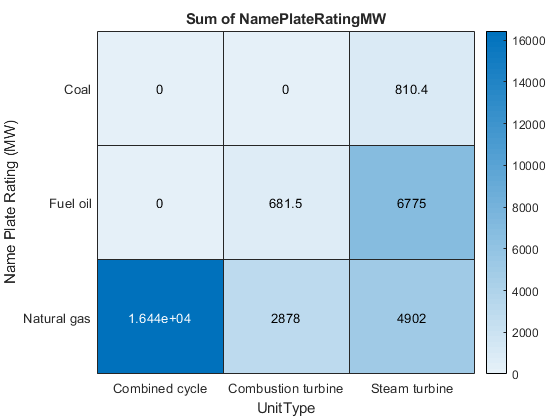

% Heat map of nameplate capacity by unit type and fuel type
figure;
heatmap(generatorCombiner, "UnitType", "FuelType", "ColorVariable", "NamePlateRatingMW", "ColorMethod","sum");
ylabel("Name Plate Rating (MW)");

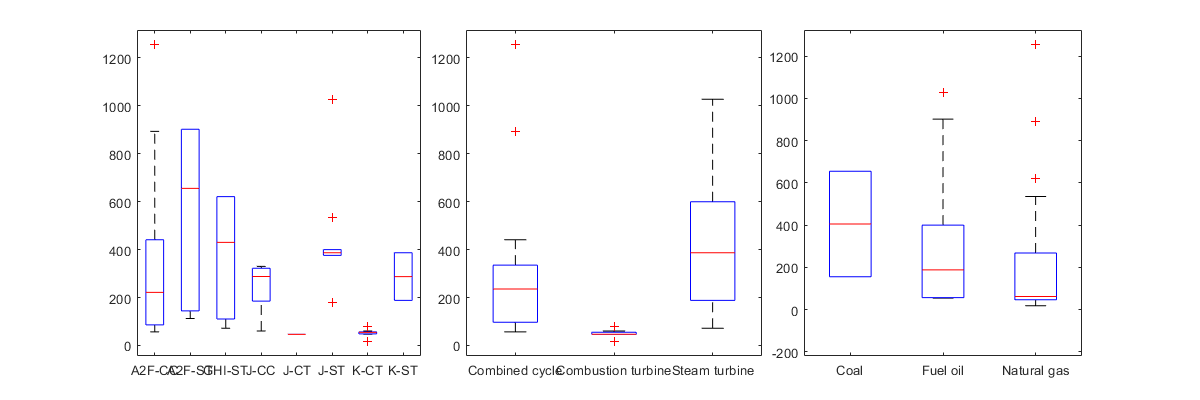

% Box plot of nameplate capacity grouped by units
figure;
subplot(1,3,1)
boxplot(generatorCombiner.NamePlateRatingMW, generatorCombiner.NYAMUnit);
subplot(1,3,2)
boxplot(generatorCombiner.NamePlateRatingMW, generatorCombiner.UnitType);
subplot(1,3,3)
boxplot(generatorCombiner.NamePlateRatingMW, generatorCombiner.FuelType);
set(gcf, "Position", [50, 50, 1200, 400]);

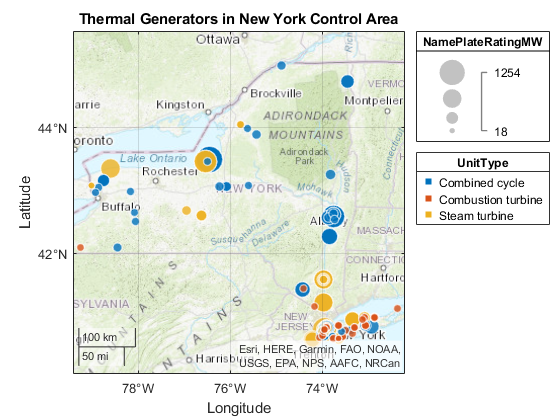

% Geobubble plot of generators grouped by unit type
figure;
gb = geobubble(RGGI2NYCA2019, "FacilityLatitude", "FacilityLongitude", "ColorVariable", "UnitType", "SizeVariable", "NamePlateRatingMW");
gb.Basemap = "topographic";
title("Thermal Generators in New York Control Area");

## Combine the generation table with the reference table

% Combine the RGGI database with the NYCA database
% Join tables
generationAllJoint = innerjoin(generationAll,generatorCombiner,'Keys',...
    {'FacilityName','FacilityID','UnitID'}, 'LeftVariables', {'FacilityName',...
    'FacilityID', 'UnitID', 'Date', 'Hour', 'GrossLoadMW', 'OperatingTime'});

## Subsetting generators by facility and calculate generation features

% Define arrays to record NYISO generators' parameter
maxPowerGen = zeros(size(NYISONames));
minPowerGen = zeros(size(NYISONames));
maxRampUpGen = zeros(size(NYISONames));
maxRampDownGen = zeros(size(NYISONames));

for i=1:length(NYISONames)
    genName = NYISONames(i);
    genSet = generationAllJoint(generationAllJoint.NYISOname == genName, :);
    [PMaxGen, PMinGen, RampUpMaxGen, RampDownMaxGen] = GenAggregator(genSet);
    maxPowerGen(i) = PMaxGen;
    minPowerGen(i) = PMinGen;
    maxRampUpGen(i) = RampUpMaxGen;
    maxRampDownGen(i) = RampDownMaxGen;
end

% Combine generator parameters into one summary table
maxRamp60Gen = (maxRampUpGen + abs(maxRampDownGen))/2;
maxRamp30Gen = maxRamp60Gen/2;
maxRamp10Gen = maxRamp30Gen/3;
maxRampAgcGen = maxRamp10Gen/10;
genSummary = table(NYISONames, maxPowerGen, minPowerGen, maxRampAgcGen);

% Add generator information to the generator summary table
genSummary = innerjoin(genSummary,generatorCombiner,'LeftKeys',...
    {'NYISONames'},'RightKeys',{'NYISOname'})

genSummary = 155×14 table
           NYISONames            maxPowerGen    minPowerGen    maxRampAgcGen     PTID            FacilityName           FacilityID    UnitID    NYAMUnit    Region         UnitType          FuelType      NamePlateRatingMW    GrossLoadMWh
    _________________________    ___________    ___________    _____________    ______    __________________________    __________    ______    ________    ______    __________________    ___________    _________________    ____________

    Allegany           

## Fit categorical linear regression model

### Linear regression model of maximum power generation (Not useful)

% lmMaxPowerGen = fitlm(genSummary, 'maxPowerGen ~ UnitType * FuelType + Region','RobustOpts','on')
% anovaMaxPowerGen = anova(lmMaxPowerGen, 'component')

### Linear regression model of maximum ramp rate (Not useful)

% lmMaxRampAgcGen = fitlm(genSummary, 'maxRampAgcGen ~ UnitType * FuelType + Region','RobustOpts','on')
% anova(lmMaxRampAgcGen, 'component')

### One way ANOVA of maximum generation and maximum ramp rate

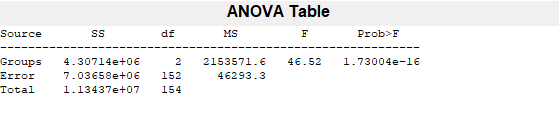

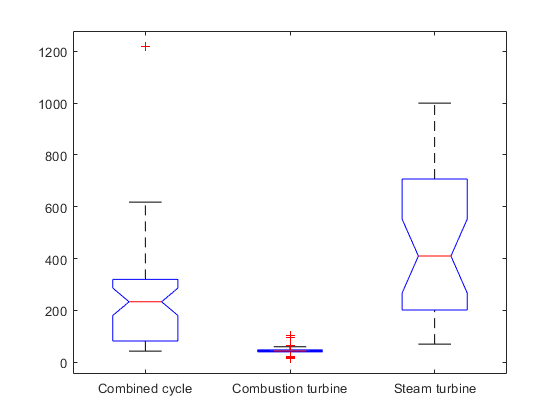

[pMaxUnit, tbMaxUnit] = anova1(genSummary.maxPowerGen, genSummary.UnitType);

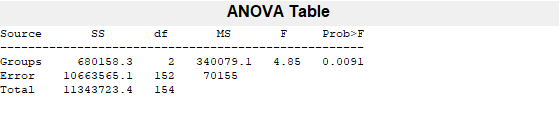

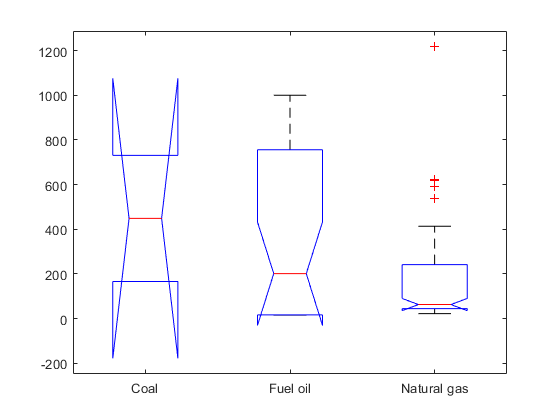

[pMaxFuel, tbMaxFuel] = anova1(genSummary.maxPowerGen, genSummary.FuelType);

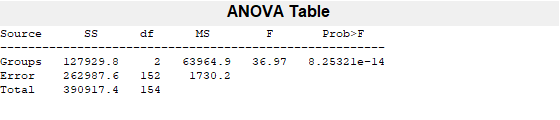

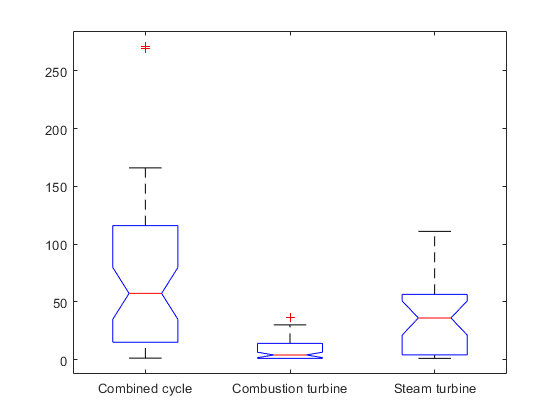

[pMinUnit, tbMinUnit] = anova1(genSummary.minPowerGen, genSummary.UnitType);

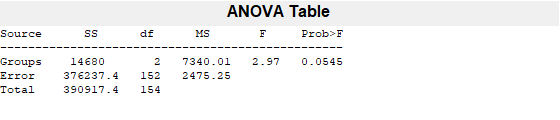

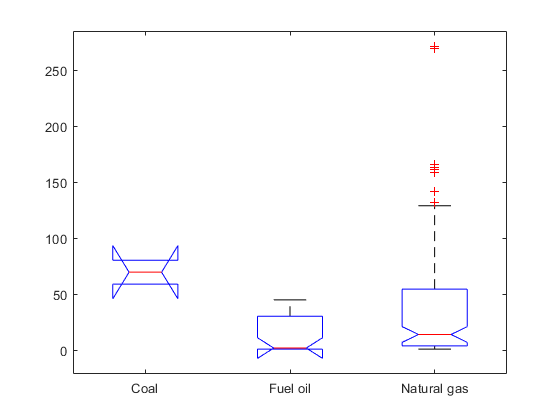

[pMinFuel, tbMinFuel] = anova1(genSummary.minPowerGen, genSummary.FuelType);

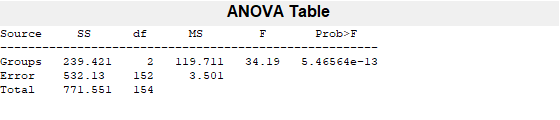

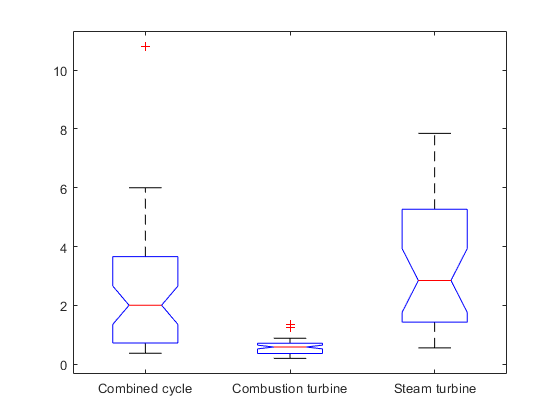

[pRampUnit, tbRampUnit] = anova1(genSummary.maxRampAgcGen, genSummary.UnitType);

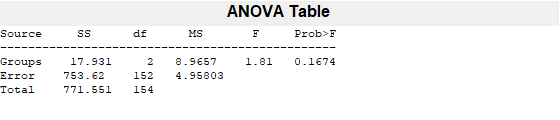

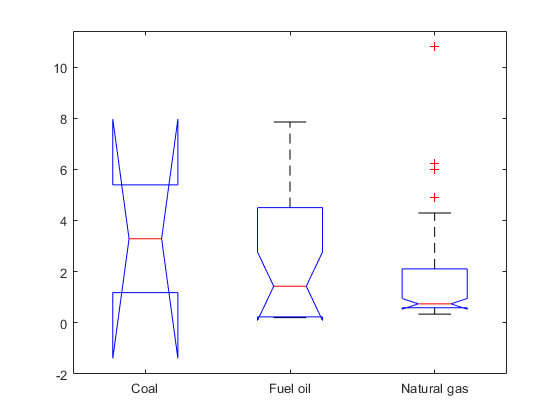

[pRampFuel, tbRampFuel] = anova1(genSummary.maxRampAgcGen, genSummary.FuelType);

### Subset the generator summary table by unit type, fuel type, and NYAM unit

% Subset the generator summary table by unit type
genSummaryCC = genSummary(genSummary.UnitType == "Combined cycle", :);
genSummaryCT = genSummary(genSummary.UnitType == "Combustion turbine", :);
genSummaryST = genSummary(genSummary.UnitType == "Steam turbine", :);
% Subset the generator summary table by fuel type
genSummaryNG = genSummary(genSummary.FuelType == "Natural gas", :);
genSummaryFO = genSummary(genSummary.FuelType == "Fuel oil", :);
genSummaryCO = genSummary(genSummary.FuelType == "Coal", :);
% Subset the generator summary table by NYAM units
genSummaryA2FCC = genSummary(genSummary.NYAMUnit == "A2F-CC", :);
genSummaryA2FST = genSummary(genSummary.NYAMUnit == "A2F-ST", :);
genSummaryGHIST = genSummary(genSummary.NYAMUnit == "GHI-ST", :);
genSummaryJCC = genSummary(genSummary.NYAMUnit == "J-CC", :);
genSummaryJCT = genSummary(genSummary.NYAMUnit == "J-CT", :);
genSummaryJST = genSummary(genSummary.NYAMUnit == "J-ST", :);
genSummaryKCT = genSummary(genSummary.NYAMUnit == "K-CT", :);
genSummaryKST = genSummary(genSummary.NYAMUnit == "K-ST", :);


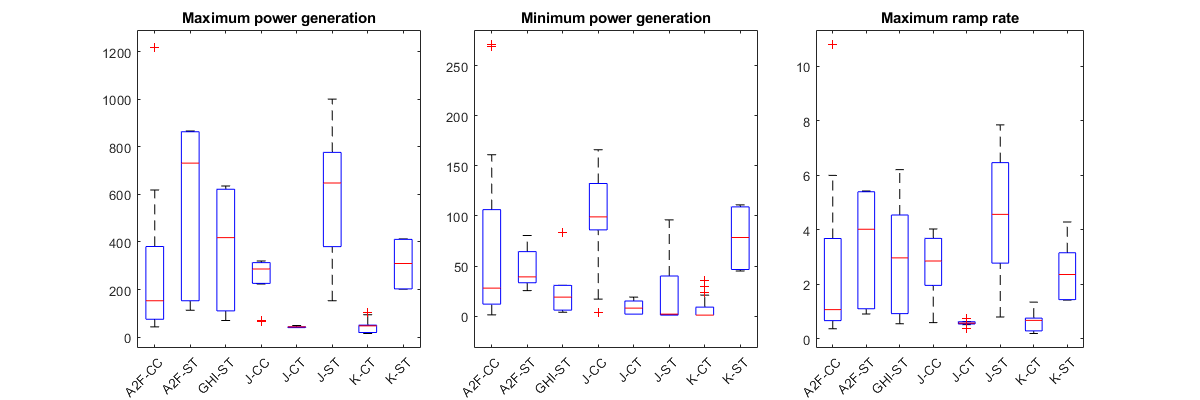

figure;
subplot(1,3,1);
boxplot(genSummary.maxPowerGen, genSummary.NYAMUnit);
title("Maximum power generation");
xtickangle(45);
subplot(1,3,2);
boxplot(genSummary.minPowerGen, genSummary.NYAMUnit);
title("Minimum power generation");
xtickangle(45);
subplot(1,3,3);
boxplot(genSummary.maxRampAgcGen, genSummary.NYAMUnit);
title("Maximum ramp rate");
xtickangle(45);
set(gcf,'Position',[100, 100, 1200, 400]);

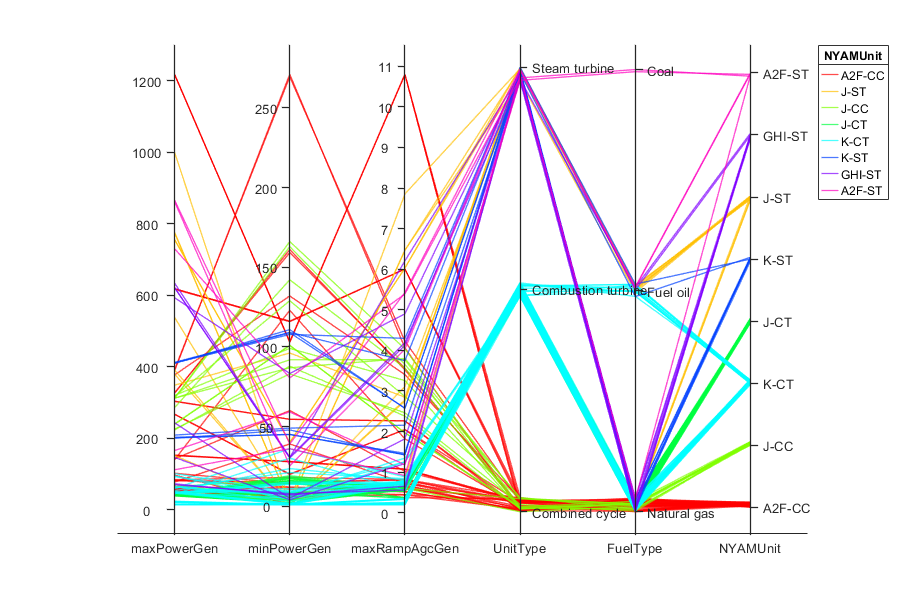

% Parallel coordinates plot
figure;
coordvars = {'maxPowerGen', 'minPowerGen', 'maxRampAgcGen', 'UnitType', 'FuelType', 'NYAMUnit'};
p = parallelplot(genSummary, "CoordinateVariables", coordvars, 'GroupVariable', "NYAMUnit", 'DataNormalization', "range");
unitsOrder = {'A2F-CC', 'J-CC', 'K-CT', 'J-CT', 'K-ST', 'J-ST','GHI-ST', 'A2F-ST'};
categoricalUnits = categorical(genSummary.NYAMUnit, unitsOrder, 'Ordinal', true);
orderUnits = reordercats(categoricalUnits, unitsOrder);
p.SourceTable.NYAMUnit = orderUnits;
fuelsOrder = {'Natural gas', 'Fuel oil', 'Coal'};
categoricalFuelTypes = categorical(genSummary.FuelType, fuelsOrder, 'Ordinal', true);
orderFuelTypes = reordercats(categoricalFuelTypes, fuelsOrder);
p.SourceTable.FuelType = orderFuelTypes;
p.Color = hsv(8);
set(gcf, 'Position', [100, 100, 900, 600]);

## Subsetting generators by NYAM Units and calculate generation features

% Loop through the NYAM units and get key features of the units
maxPowerAgg = zeros(size(NYAMUnits));
minPowerAgg = zeros(size(NYAMUnits));
maxRampUpAgg = zeros(size(NYAMUnits));
maxRampDownAgg= zeros(size(NYAMUnits));

for i=1:length(NYAMUnits)
    unitName = NYAMUnits(i);
    unitSet = generationAllJoint(generationAllJoint.NYAMUnit == unitName, :);
    [PMaxUnit, PMinUnit, RampUpMaxUnit, RampDownMaxUnit] = GenAggregator(unitSet);
    maxPowerAgg(i) = PMaxUnit;
    minPowerAgg(i) = PMinUnit;
    maxRampUpAgg(i) = RampUpMaxUnit;
    maxRampDownAgg(i) = RampDownMaxUnit;
end

% minPowerAgg = [108; 63; 42; 493; 41; 82; 27; 47];
minPowerAgg(4) = 493;
minPowerAgg(5) = 41;
maxRamp60Agg = (maxRampUpAgg + abs(maxRampDownAgg))./2;
maxRamp30Agg = maxRamp60Agg./2;
maxRamp10Agg = maxRamp60Agg./6;
maxRampAgcAgg = maxRamp60Agg./60;
nameplateRating = aggCapSummary.sum_NamePlateRatingMW;
maxCF = maxPowerAgg./nameplateRating*100;
aggSummary = table(NYAMUnits, nameplateRating, maxCF, maxPowerAgg, minPowerAgg, maxRampAgcAgg, maxRamp10Agg, maxRamp30Agg)

aggSummary = 8×8 table
    NYAMUnits    nameplateRating    maxCF     maxPowerAgg    minPowerAgg    maxRampAgcAgg    maxRamp10Agg    maxRamp30Agg
    _________    _______________    ______    ___________    ___________    _____________    ____________    ____________

     A2F-CC           13177         31.577       4161            415           9.7975           97.975          293.92   
     A2F-ST          2726.5         59.894       1633             59           4.0283           40.283          120.85   
     GHI-ST            3016         39.423       1189             28           4.3742           43.742          131.23   
     J-CC            3261.2         83.282       2716            493           6.0242         

aggSummary4NYAM = aggSummary([2, 2, 3, 6, 8, 1, 4, 5, 7], :)

aggSummary4NYAM = 9×6 table
    NYAMUnits    maxPowerAgg    minPowerAgg    maxRampAgcAgg    maxRamp10Agg    maxRamp30Agg
    _________    ___________    ___________    _____________    ____________    ____________

     A2F-ST         1633             59           4.0283           40.283          120.85   
     A2F-ST         1633             59           4.0283           40.283          120.85   
     GHI-ST         1189             28           4.3742           43.742          131.23   
     J-ST           3729             87            5.619            56.19          168.57   
     K-ST           2060             92           4.2808           42.808          128.43   
     A2F-CC         4161            415           9.7975           97.975          293.92   
     J-CC           271

### Compare the results with the data in Steve's thesis and Leah's report

maxPowerS = [5300; 2800; 2900; 3300; 2600; 3900; 2377; 2000];
minPowerS = [530; 420; 435; 330; 65; 585; 59.425; 390];
maxRampAgcS = [14.13; 3.12; 3.22; 8.8; 17.33; 4.33; 15.85; 2.89];
maxPowerL = [4517; 1882; 1831; 2147; 911; 4013; 1095; 2188];
minPowerL = [48; 1001; 733; 11; 539; 7; 303; 31];
maxRampAgcL = [20.06; 1.6; 1.48; 17.52; 1.43; 7.07; 1.86; 5.13];
genSummaryS = table(NYAMUnits, maxPowerS, minPowerS, maxRampAgcS);
genSummaryL = table(NYAMUnits, maxPowerL, minPowerL, maxRampAgcL);
genSummaryAll = join(aggSummary,genSummaryS,'Keys',{'NYAMUnits'}, 'LeftVariables', {'NYAMUnits', 'maxPowerAgg', 'minPowerAgg', 'maxRampAgcAgg'});
genSummaryAll = join(genSummaryAll, genSummaryL, 'Keys', {'NYAMUnits'})

genSummaryAll = 8×10 table
    NYAMUnits    maxPowerAgg    minPowerAgg    maxRampAgcAgg    maxPowerS    minPowerS    maxRampAgcS    maxPowerL    minPowerL    maxRampAgcL
    _________    ___________    ___________    _____________    _________    _________    ___________    _________    _________    ___________

     A2F-CC         4161            415           9.7975          5300           530         14.13         4517           48          20.06   
     A2F-ST         1633             59           4.0283          2800           420          3.12         1882         1001            1.6   
     GHI-ST         1189             28           4.3742    

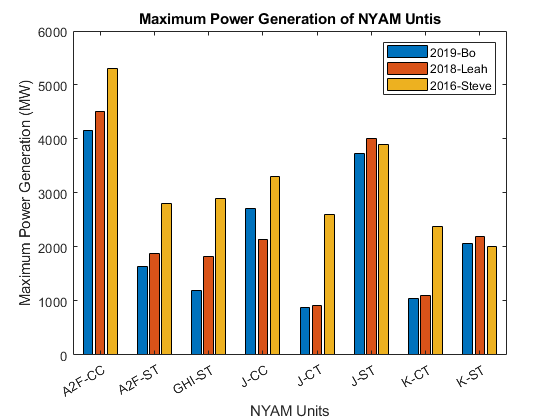

figure;
bar(genSummaryAll.NYAMUnits, [genSummaryAll.maxPowerAgg, genSummaryAll.maxPowerL, genSummaryAll.maxPowerS]);
legend("2019-Bo", "2018-Leah", "2016-Steve");
xlabel("NYAM Units");
ylabel("Maximum Power Generation (MW)");
title("Maximum Power Generation of NYAM Untis");

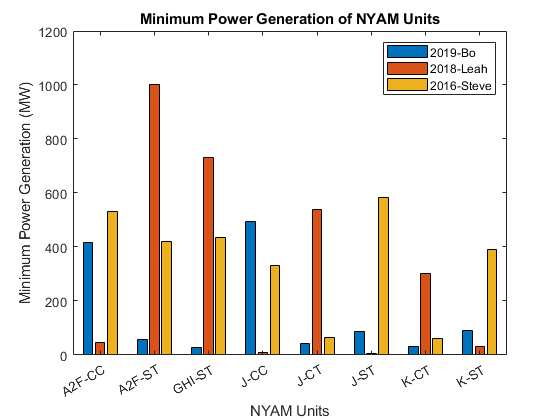

figure;
bar(genSummaryAll.NYAMUnits, [genSummaryAll.minPowerAgg, genSummaryAll.minPowerL, genSummaryAll.minPowerS]);
legend("2019-Bo", "2018-Leah", "2016-Steve");
xlabel("NYAM Units");
ylabel("Minimum Power Generation (MW)");
title("Minimum Power Generation of NYAM Units");

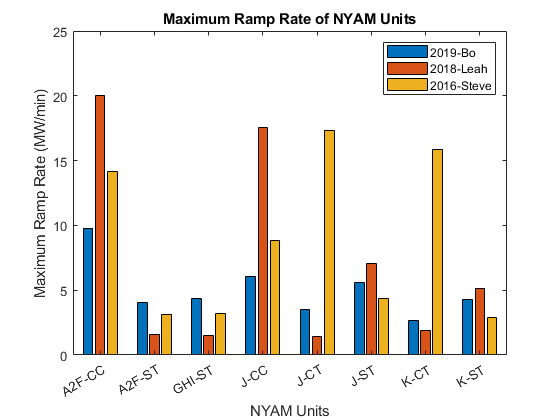

figure;
bar(genSummaryAll.NYAMUnits, [genSummaryAll.maxRampAgcAgg, genSummaryAll.maxRampAgcL, genSummaryAll.maxRampAgcS]);
legend("2019-Bo", "2018-Leah", "2016-Steve");
xlabel("NYAM Units");
ylabel("Maximum Ramp Rate (MW/min)");
title("Maximum Ramp Rate of NYAM Units");